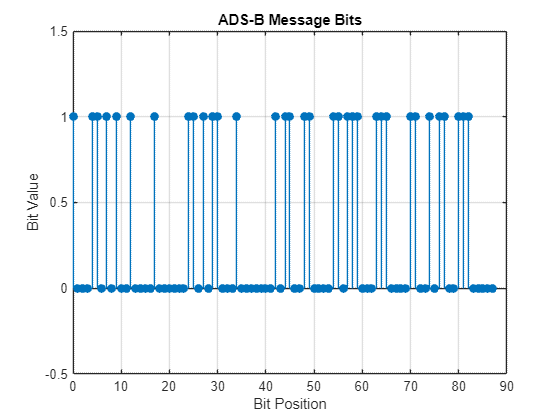

% Function to convert a character to its 6-bit binary representation
function char_bin = charToBinary6bit(char)
    if char >= 'A' && char <= 'Z'
        char_dec = double(char) - double('A') + 1; % A-Z: 1-26
    elseif char >= '0' && char <= '9'
        char_dec = double(char) - double('0') + 48; % 0-9: 48-57
    elseif char == ' '
        char_dec = 32; % space: 32
    else
        error('Invalid character for aircraft ID');
    end
    char_bin = dec2bin(char_dec, 6); % Convert decimal to 6-bit binary
end

% Function to convert binary to hexadecimal manually
function hex_str = binaryToHexManual(bin_str)
    hex_str = '';
    for i = 1:4:length(bin_str)
        nibble = bin_str(i:min(i+3, length(bin_str)));
        if length(nibble) < 4
            nibble = [nibble, repmat('0', 1, 4-length(nibble))];
        end
        dec_val = sum(2.^(3:-1:0) .* (nibble == '1'));
        if dec_val < 10
            hex_str = [hex_str, char(dec_val + '0')];
        else
            hex_str = [hex_str, char(dec_val - 10 + 'A')];
        end
    end
end

% Main code
% ADS-B Downlink Format and Capability values
DF = 17; % Downlink Format (17 base 10)
CA = 5;  % Capability (5 base 10)
ICAO_hex = '4840D6'; % ICAO address (ADFE68 in hexadecimal)

% Aircraft Identification and Category
type_code = 4; % Type Code for Aircraft Identification
category = 0; % Category for Unmanned Aerial Vehicle
aircraft_id = 'KLM1023 '; % Aircraft Identification (8 characters)

% Convert DF and CA to binary
DF_bin = dec2bin(DF, 5); % DF is 5 bits long
CA_bin = dec2bin(CA, 3); % CA is 3 bits long

% Concatenate DF and CA to form the first 8 bits of the ADS-B message
ADS_B_message = [DF_bin CA_bin];

% Convert ICAO address from hexadecimal to binary
ICAO_bin = dec2bin(hex2dec(ICAO_hex), 24);

% Convert Type Code and Category to binary
type_code_bin = dec2bin(type_code, 5); % Type Code is 5 bits long
category_bin = dec2bin(category, 3); % Category is 3 bits long

% Convert Aircraft Identification characters to binary
aircraft_id_bin = '';
for i = 1:length(aircraft_id)
    aircraft_id_bin = [aircraft_id_bin charToBinary6bit(aircraft_id(i))];
end

% Concatenate Type Code, Category, and Aircraft Identification to form the payload
payload_bin = [type_code_bin category_bin aircraft_id_bin];

% Concatenate all parts to form the complete ADS-B message
ADS_B_complete = [ADS_B_message ICAO_bin payload_bin];

% Plot the complete ADS-B message bits
figure;
stem(0:length(ADS_B_complete)-1, ADS_B_complete - '0', 'filled');
ylim([-0.5, 1.5]);
grid on;
title('ADS-B Message Bits');
xlabel('Bit Position');
ylabel('Bit Value');


% Display the final ADS-B message in binary
disp('Final ADS-B Message (Binary):');

Final ADS-B Message (Binary):


disp(ADS_B_complete);

1000110101001000010000001101011000100000001011001100001101110001110000110010110011100000



% Convert binary string to hexadecimal manually
ADS_B_hex_final = binaryToHexManual(ADS_B_complete);

disp('Final ADS-B Message (Hexadecimal):');

Final ADS-B Message (Hexadecimal):


disp(ADS_B_hex_final);

8D4840D6202CC371C32CE0
